## Preprocessing pipeline for EEG data

Mathilde Marie Duville

**Notice: depending on the nature of the raw data (i.e., presence of noisy information), it is necessary to adapt this code and otpimize the output towards the cleanest and less distorsionned data. Here, for the sake of completeness, several methods are presented. Nevertheless, only a few of them might be adequate for your data.**

This code is automated for several raw files. However, for the sake of simplicty and to decrease computation time, this example preprocesses data from one file only.

*Parallel computing may be implemented to decrease computing time (in case of large datasets; the *Parallel Computing Toolbox must be installed*)*

% mr = mapreducer();

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

clear; clc; close all; 
PathtoEEGLab = 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\';
PathtoRest_Math = 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\REST_Math';
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

*Import data*

Warning SOPEN: number of event onset (TYP=1) and event offset (TYP=8001) differ (0,1)
Warning SOPEN: number of event onset (TYP=100) and event offset (TYP=8100) differ (0,1)
Warning SOPEN: number of event onset (TYP=102) and event offset (TYP=8102) differ (0,1)
Warning SOPEN: number of event onset (TYP=104) and event offset (TYP=8104) differ (0,1)
Warning SOPEN: number of event onset (TYP=106) and event offset (TYP=8106) differ (0,1)
Warning SOPEN: number of event onset (TYP=108) and event offset (TYP=8108) differ (0,1)
Warning SOPEN: number of event onset (TYP=10A) and event offset (TYP=810A) differ (0,1)
Warning SOPEN: number of event onset (TYP=10C) and event offset (TYP=810C) differ (0,1)
Warning SOPEN: number of event onset (TYP=10E) and event offset (TYP=810E) differ (0,1)
Warning SOPEN: number of event onset (TYP=110) and event offset (TYP=8110) differ (0,1)
Warning SOPEN: number of event onset (TYP=112) and event offset (TYP=8112) differ (0,1)
Warning SOPEN: number of event ons

Creating a new ALLEEG dataset 1


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


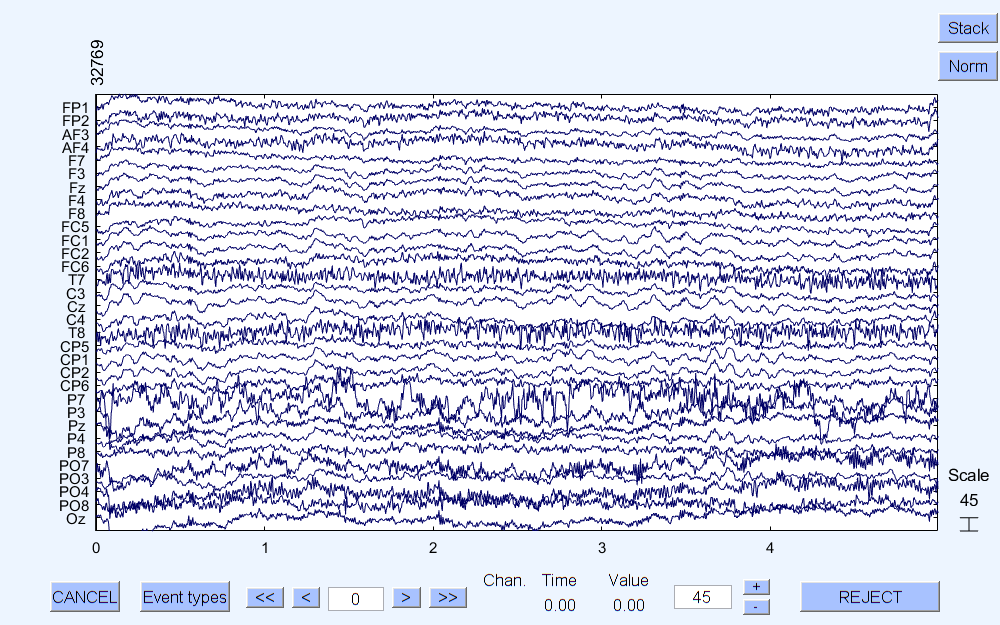

MainPath = pwd; folder = MainPath;
fileList = dir(fullfile(folder, '*.gdf'));
L=length(fileList); n = cell(1,L); 
for i = 1:L
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name; EEG = [];
   EEG = pop_biosig(fileList(i).name);
   EEG.setname = fileList(i).name; 
   [ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'setname',...
       fileList(i).name, 'gui','off');
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
   pop_eegplot(EEG, 1, 1, 1); 
end

eeglab redraw

*Edit channel location *

% File with topographic coordinates of channels; here an 32 channels were
% used with a standard extended 10-20 topography
chanloc = 'standard_1020.elc'; L=length(ALLEEG);
for i = 1:L
    EEG =[]; EEG = ALLEEG(i);
    CURRENTSET = i;
    EEG = pop_chanedit(EEG, 'lookup',[MainPath, '\', chanloc]);
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
end

readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 200
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


eeglab redraw;

*Re-referencing. Here, an average referencing is showed. Note that average referencing is recommended with high-density topographies because low sensor density may induce the lack of representativity of the ideal “zero reference. However, average referencing would subtract globalized topographical data to outline localized activity. The reference may be changed by specifiying the index of the name of the reference electrode between brackets (2nd input of the function) pop_reref. *

*Also, a code for *REST re-referencing (Dong, L., Li, F., Liu, Q., Wen, X., Lai, Y., Xu, P., & Yao, D. (2017). MATLAB Toolboxes for Reference Electrode Standardization Technique (REST) of Scalp EEG. *Frontiers in Neuroscience*, *11*, 601. [https://doi.org/10.3389/fnins.2017.00601)](https://doi.org/10.3389/fnins.2017.00601))  *is proposed at the end of this document as it is highly sensitive to noise. Note that high electrode density is also recommended. *

for i = 1:L
    subjs=1:L; EEG =[]; EEG = ALLEEG(i);
    EEG = pop_reref(EEG,[]);
    CURRENTSET = i;
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-Reref'];
    EEG.filename =['Part' num2str(subjs(i),'%03.f') '-Reref'];
    EEG.condition = 'Scenario1';
    EEG.group = 'Treatment';
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
end

Re-referencing data


eeglab redraw

*Substract channel baseline means*

for i = 1:L
    EEG =[]; EEG = ALLEEG(i);
    CURRENTSET = i;
    EEG = pop_rmbase(EEG, [],[]);
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-rmbase'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-rmbase'];    
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
end

pop_rmbase(): Removing baseline...


eeglab redraw

*Filter the signal between the ranges of EEG.  [0.1-100]. *

*Check the response frequency of the filter. IIR filters have the advantage of not creating any  ripples in passband nor in stopband. Depending on the study, frequencies of interest must not be distorsioned (lower amplitude in transition band). Adjust the filter adequately and alway check the magnitude and phase responses of the filter. Filter forward and reverse to avoid phase delay*

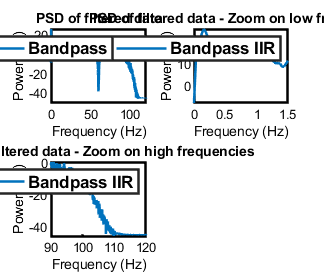

bpfilter = designfilt('bandpassiir','FilterOrder',8, ...
    'HalfPowerFrequency1',0.1,'HalfPowerFrequency2',100, ...
    'DesignMethod','butter','SampleRate',EEG.srate); 

% See Magnitude and Phase responses
fvtool(bpfilter)

% Trial to check filtering by visaulization of PSD
% Filter forward and reverse to avoid phase delay
data2filter   = squeeze(double(ALLEEG(1).data(14,:)));
resultbpfilter = single(filtfilt(bpfilter, double(data2filter')))'; 
[pxx_bpfilter,f_bpfilter] = pwelch(resultbpfilter,[],[],[],EEG.srate);

% Notice: here, data were online filtered at 60 Hz to remoise line noise,
% that explains the drop in power around 60 Hz
figure()
subplot(2,2,1)
plot(f_bpfilter, db(pxx_bpfilter, 'power'),LineWidth=1.5)
xlim([0 120]);
legend('Bandpass IIR', 'FontWeight', 'bold', 'fontname', 'Arial',...
    'FontSize', 10)
ax = gca;set(ax,'LineWidth',1.5); title('PSD of filtered data')
set(ax, 'XColor', 'k', 'YColor','k'); 
xlabel('Frequency (Hz)'); ylabel('Power (dB)')

subplot(2,2,2)
plot(f_bpfilter, db(pxx_bpfilter, 'power'),LineWidth=1.5)
xlim([0 1.5]);
legend('Bandpass IIR', 'FontWeight', 'bold', 'fontname', 'Arial',...
    'FontSize', 10)
ax = gca;set(ax,'LineWidth',1.5); title('PSD of filtered data - Zoom on low frequencies')
set(ax, 'XColor', 'k', 'YColor','k'); 
xlabel('Frequency (Hz)'); ylabel('Power (dB)')

subplot(2,2,3)
plot(f_bpfilter, db(pxx_bpfilter, 'power'),LineWidth=1.5)
xlim([90 120]);
legend('Bandpass IIR', 'FontWeight', 'bold', 'fontname', 'Arial',...
    'FontSize', 10)
ax = gca;set(ax,'LineWidth',1.5); title('PSD of filtered data - Zoom on high frequencies')
set(ax, 'XColor', 'k', 'YColor','k'); 
xlabel('Frequency (Hz)'); ylabel('Power (dB)')
set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])


% Apply filter on data
for i = 1:L
    EEG =[]; EEG = ALLEEG(i);CURRENTSET = i;
    EEG.data = single(filtfilt(bpfilter, double(EEG.data')))'; 
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-Bp-filtered'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-Bp-filtered'];    
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
end
eeglab redraw

*In case of needing line noise removal, the Cleanline plug-in may be used. Please, see the PowerPoint slide dedicated to it for a more detailed explanation (TheoreticalExplanations.pdf) and the "cleanline" function of EEGLab for explanation of every input. *

pathOUT = pwd;
for i = 1:L
    EEG =[]; EEG = ALLEEG(i); CURRENTSET = i;
    EEG = pop_cleanline(EEG, 'Bandwidth',2,'ChanCompIndices',1:EEG.nbchan,                  ...
                             'SignalType','Channels','ComputeSpectralPower',true,             ...
                             'LineFrequencies',60 ,'NormalizeSpectrum',false,           ...
                             'LineAlpha',0.01,'PaddingFactor',2,'PlotFigures',false,          ...
                             'ScanForLines',true,'SmoothingFactor',100,'VerboseOutput',1,    ...
                             'SlidingWinLength',4,'SlidingWinStep',1);
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-Cleanline'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-Cleanline'];    
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
    pop_saveset(EEG, 'filename',['Part' num2str(subjs(i),'%03.f') '-Cleanline'],...
        'filepath', pathOUT); 
end



Welcome to the CleanLine line noise removal toolbox!
CleanLine is written by Tim Mullen (tim@sccn.ucsd.edu) and uses multi-taper routines modified from the Chronux toolbox (www.chronux.org)

Tsk Tsk, you've allowed your data to get very dirty!
Let's roll up our sleeves and do some cleaning!
Today we're going to be cleaning your Channels

[!] Please note that because the selected window length does not divide the data length, 
    1 seconds of data at the end of the record will not be cleaned.

Multi-taper parameters follow:
	Time-bandwidth product:	 4
	Number of tapers:	 7
	Number of FFT points:	 4096
I'm going try to remove lines at these frequencies: [60] Hz
I'm going to scan the range +/-1 Hz around each of the above frequencies for the exact line frequency.
I'll do this by selecting the frequency that maximizes Thompson's F-statistic above a threshold of p=0.01.

OK, now stand back and let The Maid show you

Saving dataset...


eeglab redraw

*Bad channels detection: *

*Please see the "clean_rawdata" function of EEGLab.*

*Low-frequency drifts are withdrawn by a forward–backward finite impulse response filter (Kaiser window, transition band [0.25 0.75] Hz stopband attenuation 80 dB).*

*Bad channels are detected whenever they presented: (1) more than 5 s flatline, (2) higher line noise data than four standard deviations of the total channel population, or (3) joint probability exceeding three standard deviations from the average of the probability density function of the total channel sample.*

*High-variance spontaneous artifacts are corrected using the Artifact Subspace Reconstruction (ASR) algorithm. *

*Bad channels are removed, and the superfast spherical spline interpolation method was used to interpolate them (m = 4, n = 7).*

*Please, see the PowerPoint slide dedicated to ASR and superfast spherical spline interpolation for a more detailed explanation (TheoreticalExplanations.pdf)*

for i = 1:1:L
    EEG =[]; EEG = ALLEEG(i); CURRENTSET = i;
    try EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,...
        'ChannelCriterion','off','LineNoiseCriterion',4,...
        'Highpass',[0.25 0.75],'BurstCriterion',3,'WindowCriterion','off',...
        'BurstRejection','off','Distance','Euclidian',...
        'WindowCriterionTolerances','off');
    catch disp('Error')
    end
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-ASR_BC'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-ASR_BC'];  
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
    pop_saveset(EEG, 'filename',['Part' num2str(subjs(i),'%03.f') '-ASR_BC'],...
        'filepath', pathOUT); 
end

Scanning for bad channels...
clean_channel:   1/16 blocks, 0.0 minutes remaining.
clean_channel:   2/16 blocks, 0.0 minutes remaining.
clean_channel:   3/16 blocks, 0.0 minutes remaining.
clean_channel:   4/16 blocks, 0.0 minutes remaining.
clean_channel:   5/16 blocks, 0.0 minutes remaining.
clean_channel:   6/16 blocks, 0.0 minutes remaining.
clean_channel:   7/16 blocks, 0.0 minutes remaining.
clean_channel:   8/16 blocks, 0.0 minutes remaining.
clean_channel:   9/16 blocks, 0.0 minutes remaining.
clean_channel:  10/16 blocks, 0.0 minutes remaining.
clean_channel:  11/16 blocks, 0.0 minutes remaining.
clean_channel:  12/16 blocks, 0.0 minutes remaining.
clean_channel:  13/16 blocks, 0.0 minutes remaining.
clean_channel:  14/16 blocks, 0.0 minutes remaining.
clean_channel:  15/16 blocks, 0.0 minutes remaining.
clean_channel:  16/16 blocks, 0.0 minutes remaining.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 68.0% (58 seconds) of t

Saving dataset...


eeglab redraw

*pop_clean_rawdata without removing bad channels on data after cleanline*

for i = 1:L
    EEG_r = []; EEG_r = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-Cleanline.set'], 'filepath', pathOUT);
    EEG =[]; CURRENTSET = []; CURRENTSET = i;
    try EEG = pop_clean_rawdata(EEG_r, 'FlatlineCriterion','off',...
        'ChannelCriterion','off','LineNoiseCriterion','off',...
        'Highpass',[0.25 0.75],'BurstCriterion',3,...
        'WindowCriterion','off','BurstRejection','off',...
        'Distance','Euclidian','WindowCriterionTolerances','off' );

         [~, chan2interp] = pop_rejchan(EEG, 'elec', 1:EEG.nbchan, 'threshold', 3, ...
            'norm', 'on', 'measure', 'prob');
        bad_channels{1,i} = chan2interp;

    catch disp('Error')
        EEG = EEG_r;
    end
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-ASR_noBC'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-ASR_noBC']; 
    pop_saveset(EEG, 'filename',['Part' num2str(subjs(i),'%03.f') '-ASR_noBC'],...
        'filepath', pathOUT); 
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-Cleanline.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-Cleanline.fdt'...


Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 68.0% (58 seconds) of the data.
eeg_insertbound(): 17 boundary (break) events added.
eeg_insertbound(): 17 boundary (break) events added.
There was an issue storing removed channels in pop_select
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 23 blocks.......................
Use vis_artifacts to compare the cleaned data to the original.
Done.


Computing probability for channels...
1 electrodes labeled for rejection
#	Elec.	Measure
1	FP1	-1.10
2	FP2	-0.77
3	AF3	-0.70
4	AF4	-0.25
5	F7	-0.50
6	F3	-1.44
7	Fz	0.51
8	F4	0.36
9	F8	1.57
10	FC5	0.42
11	FC1	1.72
12	FC2	0.89
13	FC6	0.71
14	T7	0.97
15	C3	0.33
16	Cz	0.73
17	C4	1.75
18	T8	-0.25
19	CP5	-0.18
20	CP1	0.94
21	CP2	1.37
22	CP6	0.96
23	P7	-4.12	*Bad*
24	P3	0.66
25	Pz	-1.88
26	P4	0.63
27	P8	-0.03
28	PO7	-1.28
29	PO3	1.26
30	PO4	0.20
31	PO8	-2.70
32	Oz	-2.55
Removing 1 channel(s)...


Saving dataset...


eeglab redraw

*Interpolation of bad channels*

bc_index = cell(1,L); bad_channels_tot = cell(L,1);
for i = 1:L
    EEG =[]; EEG = ALLEEG(i); CURRENTSET = []; CURRENTSET = i;
    channels_tot = []; channels_tot = (extractfield(EEG.chanlocs,'labels'))';
    
    EEG_ASR_BC = []; EEG_ASR_BC = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-ASR_BC.set'], 'filepath', pathOUT);
    channels_BC = []; channels_BC = (extractfield(EEG_ASR_BC.chanlocs,'labels'))';
    
    h = []; h = ismember(channels_tot,channels_BC);
    bad_channels_index = []; [bad_channels_index] = find(h == 0);
    bad_channels_index = (bad_channels_index)';
    bc_index{1,i} = bad_channels_index; 
    % Add bad channels from joint probability
    bc_jp = bad_channels{1,i};
    bad_channels_tot1 = unique([bc_jp, bad_channels_index]);
    bad_channels_tot{i,1} = bad_channels_tot1;
    % Write into an Excel files to track bad channels
    writecell(bad_channels_tot, 'bad_channels.xlsx')
    
    EEG = pop_interp(EEG, bad_channels_tot1, 'spherical');
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-BC_interp'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-BC_interp']; 
    [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
    pop_saveset(EEG, 'filename',['Part' num2str(subjs(i),'%03.f') '-BC_interp'],...
        'filepath', pathOUT); 
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-ASR_BC.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-ASR_BC.fdt'...


Removing 1 channel(s)...
Interpolating missing channels...


Saving dataset...


eeglab redraw 

*The signal is then high pass filtered using Butterworth 8th order with a cutoff frequency of 1 Hz, to be able to run the extended Infomax into independent components analysis (ICA). Components are transferred on non-Butterworth-filtered data, and the ones labeled within the “brain” category with less than 70% confidence by the ICLabel plug-in are rejected (constant fixed-sourced artifacts removal).*

*Please, see the PowerPoint slide dedicated to ICA and ICLabel for a more detailed explanation (TheoreticalExplanations.pdf; the Wavelet ICA algorithm is also presented as a comparison with ICLabel).*

filtICA = designfilt('highpassiir','FilterOrder',8, ...
   'HalfPowerFrequency',1, 'DesignMethod','butter','SampleRate',EEG.srate);
for i = 1:L
    EEG_ff = []; EEG_ff = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-BC_interp.set'], 'filepath', pathOUT);
    EEG_ff.data = single(filtfilt(filtICA, double(EEG_ff.data')))'; 
    EEG_ff.setname = ['Part' num2str(subjs(i),'%03.f') '-Bp-ICA'];
    EEG_ff.filename = ['Part' num2str(subjs(i),'%03.f') '-Bp-ICA'];
    EEGica = []; EEGica = pop_runica(EEG_ff, 'icatype', 'runica', ...
              'extended',1,'interrupt','off');
    pop_saveset(EEGica, 'filename',['Part' num2str(subjs(i),'%03.f') '-Bp-ICA'],...
        'filepath', pathOUT);  
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-BC_interp.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-BC_interp.fdt'...


Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [32,21760] = 32 channels, 21760 frames/nFinding 32 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 21 frames per ICA weight ((1024)^2 = 21760 weights, Initial learning rate will be 0.001, block size 50.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -77.1546 to 60.1233
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lrate 0.001000, wchange 12.34806358, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 0.13515489, angledelta  0.0 deg
step 3 - lrate 0.

Scaling components to RMS microvolt
Saving dataset...



for i = 1:L
    EEG = []; EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-BC_interp.set'], 'filepath', pathOUT);
    EEGica = []; EEGica = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-Bp-ICA.set'], 'filepath', pathOUT);
    EEG.icawinv = EEGica.icawinv; EEG.icaact = EEGica.icaact;
    EEG.icasphere = EEGica.icasphere; EEG.icaweights = EEGica.icaweights;
    EEG.icachansind = EEGica.icachansind;
    EEG.setname = ['Part' num2str(subjs(i),'%03.f') '-ICA'];
    EEG.filename = ['Part' num2str(subjs(i),'%03.f') '-ICA'];
    pop_saveset(EEG, 'filename', ['Part' num2str(subjs(i),'%03.f') '-ICA'],...
        'filepath', pathOUT); 
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-BC_interp.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-BC_interp.fdt'...


pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-Bp-ICA.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-Bp-ICA.fdt'...
Scaling components to RMS microvolt


Scaling components to RMS microvolt
Saving dataset...



ICAp='IClabel';
for i = 1:L
    EEG = []; EEGf = []; CURRENTSET = []; 
    if strcmp(ICAp,'MARA')% Similar to ICLabel.Howvwer, the databaset has not been updated since 2014.
        EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-ICA.set'], 'filepath', pathOUT);
        [~,EEGf,~] = processMARA(ALLEEG,EEG,CURRENTSET);
        EEGf = pop_subcomp(EEGf,find(EEGf.reject.gcompreject),0,0); 
    elseif strcmp(ICAp,'IClabel') % Drawback: some EEG data is lost while removing components
        try EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-ICA.set'], 'filepath', pathOUT);
            EEGf = iclabel(EEG);
            % The threshold below will select component if they are in the brain
            % category with less than 70% confidence
            EEGf = pop_icflag(EEGf, [0 0.7;0 0; 0 0; 0 0; 0 0; 0 0; 0 0]);
            EEGf = pop_subcomp(EEGf,find(EEGf.reject.gcompreject),0,0);
            numb_icacomp_rejected{i,1} = size(channels_tot,1) - size(EEGf.icaweights,1);
            writecell(numb_icacomp_rejected, 'numb_icacomp_rejected.xlsx') %Keep track of number of rejected components
            catch disp(['No components ok - i=' num2str(i)])
                ICAp='WICA'; EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-ICA.set'], 'filepath', pathOUT);
                channs = 1:EEG.nbchan;
                [wIC,A,~,~] = wICA(EEG.data(channs,:), [], 1, 0, EEG.srate);
                            artifacts = A*wIC; 
                            EEGf = EEG;
                            EEGf.data(channs,:) = EEG.data(channs,:)-artifacts;        
        end
    elseif strcmp(ICAp,'WICA') % No EEG activity is lost, however, voltage magnitudes are lower
        EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-ICA.set'], 'filepath', pathOUT);
        channs = 1:EEG.nbchan;
        [wIC,A,~,~] = wICA(EEG.data(channs,:), [], 1, 0, EEG.srate);
                    artifacts = A*wIC; 
                    EEGf = EEG;
                    EEGf.data(channs,:) = EEG.data(channs,:)-artifacts; 
    end   
    EEGf.setname = ['Part' num2str(subjs(i),'%03.f') '-' ICAp '-Clean'];
    EEGf.filename = ['Part' num2str(subjs(i),'%03.f') '-' ICAp '-Clean'];
    CURRENTSET = i; [ALLEEG, EEG] = eeg_store(ALLEEG, EEGf, CURRENTSET);
    EEGf=pop_saveset(EEGf, 'filename', ['Part' num2str(subjs(i),'%03.f') '-' ICAp '-Clean'], 'filepath', pathOUT);
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-ICA.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-ICA.fdt'...
Scaling components to RMS microvolt


ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


Saving dataset...


eeglab redraw

*REST-Referencing (in case this option is chosen)*

*Note: the original code from the pluging of *Dong and colleagues has been modified to allow the automation.

for i = 1:L
   EEG = pop_loadset('filename', ['Part' num2str(subjs(i),'%03.f') '-' ICAp '-Clean.set'], 'filepath', pathOUT);
   CURRENTSET = []; CURRENTSET = i; [ALLEEG, EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);
   eeglab redraw
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-IClabel-Clean.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing\Part001-IClabel-Clean.fdt'...


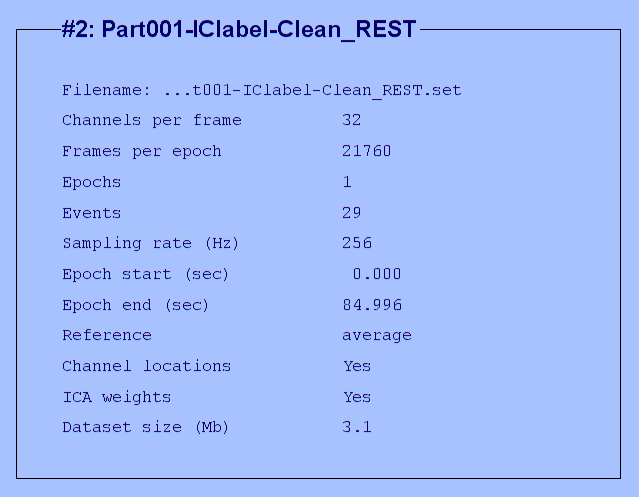

EEG1 = struct with fields:
             setname: 'Part001-IClabel-Clean'
            filename: 'Part001-IClabel-Clean.set'
            filepath: 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Preprocessing'
             subject: ''
               group: 'Treatment'
           condition: 'Scenario1'
             session: []
            comments: 'Original file: Part01.gdf'
              nbchan: 32
              trials: 1
                pnts: 21760
               srate: 256
                xmin: 0
                xmax: 84.9961
               times: [0 3.9062 7.8125 11.7188 15.6250 19.5312 23.4375 27.3438 31.2500 35.1562 39.0625 42.9688 46.8750 50.7812 54.6875 58.5938 62.5000 66.4062 70.3125 74.2188 78.1250 82.0312 85.9375 89.8438 93.7500 97.6562 101.5625 105.4688 109.3750 … ]
                data: [32×21760 single]
              icaact: []
             icawinv: [32×12 double]
           icasphere: [32×32 double]
          icaweights: [12×32 double]
         icachansind: [1 2

----------------------------
Loading Lead Field...
Calculating leadfield based on 3-concentric spheres headmodel at once...
3 concentric spheres are used
No. of electrodes: 32
electrodes do not ly on sphere surface -> using projection
No. of diples: 3000
some dipoles are not within sphere 1 -> rescale xyz coordinates of all dipoles
Lead Field Matrix: 3000 sources X 32 channels
Loading EEG data...
Current data set: Part001-IClabel-Clean
EEG data: 32 channels X 21760 time points
Checking original reference...
Re-referencing to REST...
Completed...
A new dataset was created with the REST reference
Saving dataset...



addpath(PathtoRest_Math);

pop_REST_reref();
% Press Run Button on Graphical Interface
h3 = findobj(pop_REST_reref,'tag','Run_pushbutton3'); %get handle of the push button
feval(get(h3,'Callback'),h3,[]);


% Close graphical interface for REST
close(pop_REST_reref);

*Plot data *

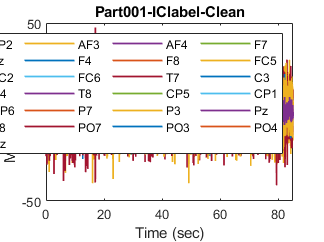

% Check for no unusual peak of magnitude
% figure("WindowState","maximized")
for i =1:L
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        EEG = []; EEG = ALLEEG(i);
        plot(EEG.times/1000, EEG.data(j,:),LineWidth=1) %times in sec
        hold on 
    end
    title(EEG.setname)
    xlim([0 max(EEG.times/1000)]);
%     xlim([1 1.5]);
    xlabel("Time (sec)"); ylabel("Magnitude (\muV)")
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
    'Location', 'northeast', 'NumColumns', 5)
end

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


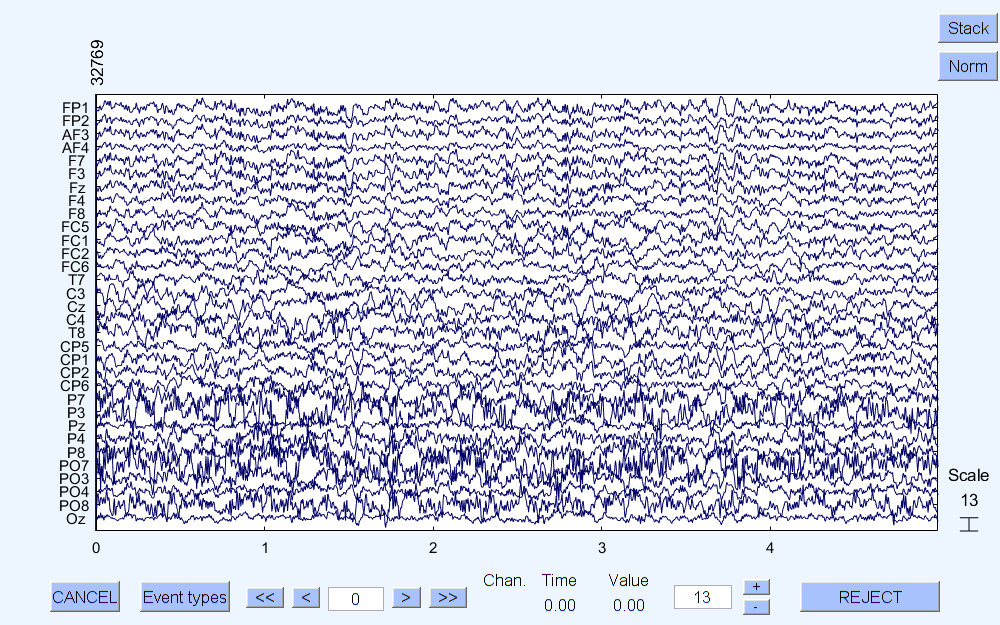


% Average referencing
for i = 1:L
    EEG = []; EEG = ALLEEG(i);
    pop_eegplot(EEG, 1, 1, 1); 
end

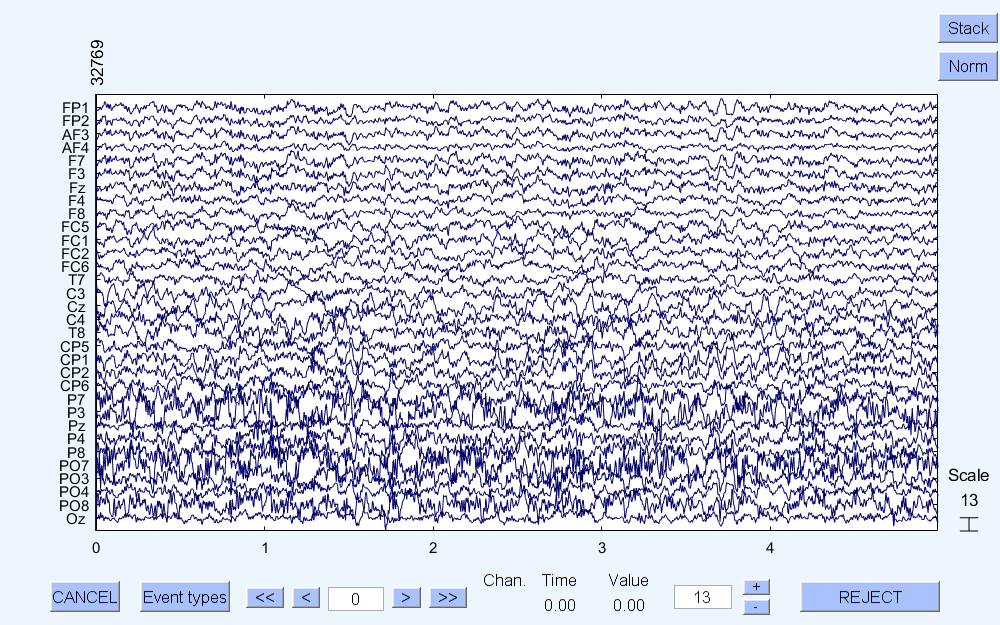


% REST referencing
for i = L+1:2*L
    EEG = []; EEG = ALLEEG(i);
    pop_eegplot(EEG, 1, 1, 1); 
end

Plot Power Spectral Densities

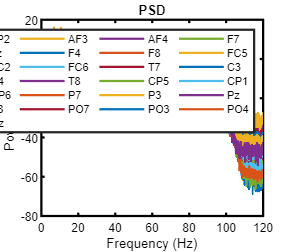

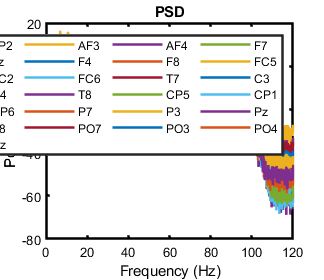

% Average referencing, then REST referencing
for i =1:size(ALLEEG,2)
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        [pxx,f] = pwelch(ALLEEG(i).data(j,:),[],[],[],ALLEEG(i).srate);
        plot(f, db(pxx, 'power'),LineWidth=1.5)
        hold on 
    end
    title(EEG.setname); xlim([0 120]);
    ax = gca;set(ax,'LineWidth',1.5); title('PSD')
    set(ax, 'XColor', 'k', 'YColor','k'); 
    xlabel('Frequency (Hz)'); ylabel('Power (dB)')
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
       'Location', 'northeast', 'NumColumns', 5)
    set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])
end

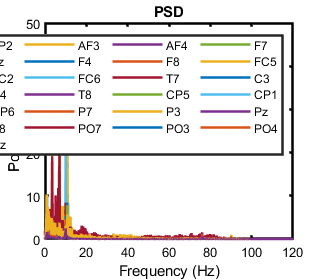

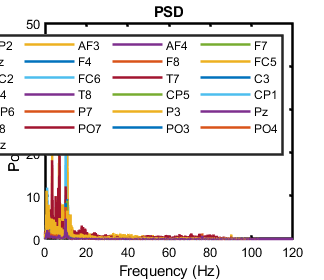



% Average referencing, then REST referencing
for i =1:size(ALLEEG,2)
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        [pxx,f] = pwelch(ALLEEG(i).data(j,:),[],[],[],ALLEEG(i).srate);
        plot(f, pxx,LineWidth=1.5)
        hold on 
    end
    title(EEG.setname);xlim([0 120]);
    ax = gca;set(ax,'LineWidth',1.5); title('PSD')
    set(ax, 'XColor', 'k', 'YColor','k'); 
    xlabel('Frequency (Hz)'); ylabel('Power (\muV^2)')
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
       'Location', 'northeast', 'NumColumns', 5)
    set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])
end

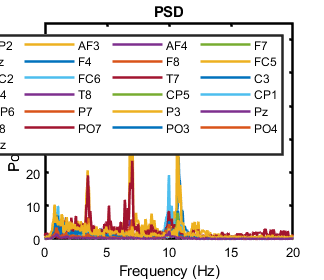

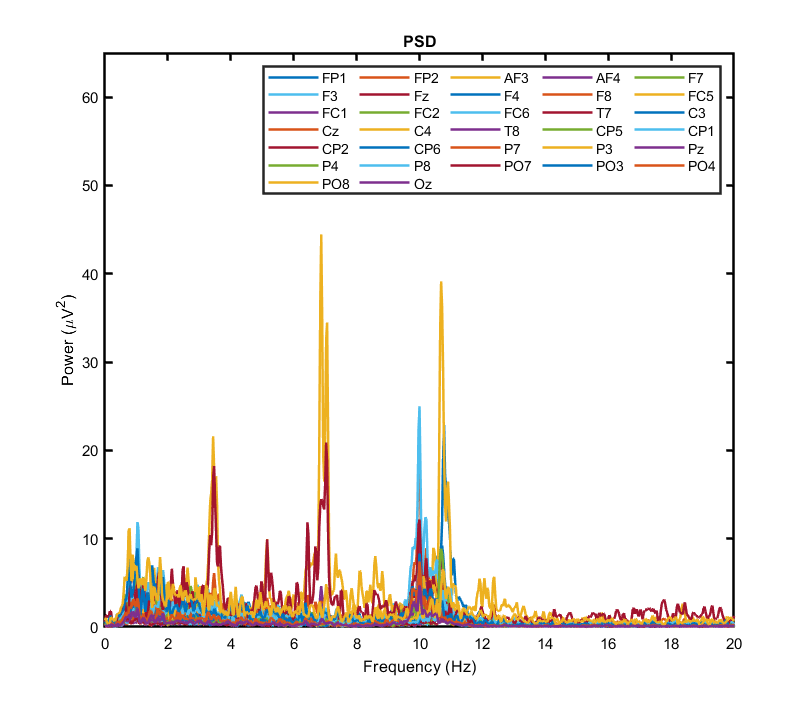


% Zoom on frequencies of interest
% Average referencing, then REST referencing
for i =1:size(ALLEEG,2)
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        [pxx,f] = pwelch(ALLEEG(i).data(j,:),[],[],[],ALLEEG(i).srate);
        plot(f, pxx,LineWidth=1.5)
        hold on 
    end
    title(EEG.setname); xlim([0 20]); ylim([0 65])
    ax = gca;set(ax,'LineWidth',1.5); title('PSD')
    set(ax, 'XColor', 'k', 'YColor','k'); 
    xlabel('Frequency (Hz)'); ylabel('Power (\muV^2)')
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
       'Location', 'northeast', 'NumColumns', 5)
    set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])
end